# Datos recibidos


% read2 = read_float_binary('SENT.bin')';

% figure
% plot(read2(1:10000))
% title("Data a enviar modulada por cos(t)")

tic
fprintf('Distancia = %d, Medicion #%d\n', d, m);

Distancia = 10, Medicion #1


rec = read_float_binary('TEST_OOK_NOGAIN.bin')';
rec_quad = read_float_binary('RX_QUAD.bin')';

% rec = (rec - rec_quad);

% Construct the two candidate signals
rec_minus = rec - rec_quad;
rec_plus  = rec + rec_quad;

% Calculate power by summing squared magnitudes
power_minus = sum(rec_minus.^2);
power_plus  = sum(rec_plus.^2);

% Choose the signal with the higher power
if power_minus > power_plus
    rec = rec_minus;
else
    rec = rec_plus;
end

%rec = modulatedSignalTx;

% figure
% plot(rec(1:20000))
% title("Data recibida por radio")


% Suppose you have:
%   modulatedSignal = <16-bit preamble, each bit upsampled 100 times, length 1600>
%   rxSignal        = <your captured signal from hardware, presumably >1600 samples>
%rxSignal = (rec-mean(rec(1000:end)));
rxSignal = rec;

% Call the function
[startIdx, corrVal, lags] = findPreambleStart(rxSignal, modulatedSignal);

% Now 'startIdx' should be the sample index in 'rxSignal' 
% where the preamble aligns best with 'modulatedSignal'.
fprintf('Estimated preamble start index = %d\n', startIdx);

Estimated preamble start index = 5633


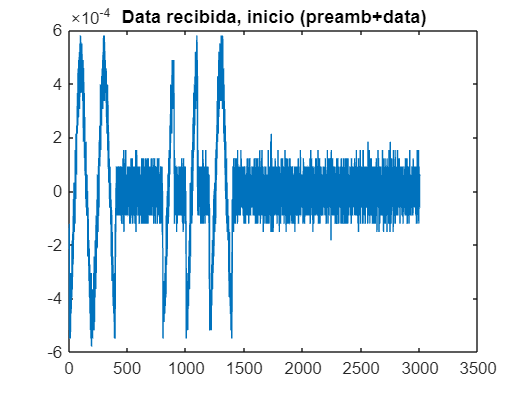


figure
plot(rxSignal(startIdx:startIdx+3000))
title("Data recibida, inicio (preamb+data)")



% If your actual BPSK data starts right after the preamble, 
% the data start would be:
dataStartIdx = startIdx + length(modulatedSignal);


% You can then extract your BPSK data samples from rxSignal like:
bpskData = rxSignal(dataStartIdx : end);

newrec_packet = bpskData;

%remove preamble
% newrec_packet = newrec(1+length(preamble)*100:end);
% 
% %normalizar respecto a señal recibida
% 
% %newrec_packet = newrec_packet/max(newrec_packet);
% 
% %normalizar respecto a canal H (remover gain)
% 
% newrec_packet = newrec_packet;%*MAX_H;

% figure
% plot(newrec_packet)
% title("Data recibida, solo data, ganancia removida")


% 1) Known or pre-calculated parameters:
Fs = 2e6;            % Sampling frequency
bitsPerPreamb = 16;  
samplesPerBit = 100; % for OOK preamble
preambleLen   = bitsPerPreamb * samplesPerBit;  % 16*100 = 1600


% BPSK parameters
sps        = samplesPerSym;   % samples per BPSK symbol
span       = span;    % RRC span in symbols
rrcFiltLen = span*sps + 1;  % e.g. 6*10 + 1 = 61
lenH       = length(H);

% Data (with H) section length:
dataBits        = numSymbols;
dataWithH_samps = length(txChannelOut);

% 2) Suppose you've already done preamble detection and found 'pktStart'
%    For example:
pktStart = startIdx;  % This is an example index where the OOK preamble begins

% 3) Segment the OOK preamble:
preambleStart = pktStart;
preambleEnd   = preambleStart + preambleLen - 1;
rxPreamble    = rxSignal(preambleStart : preambleEnd);


% GAIN COMPENSATION

% % Calculate RMS power of both signals
% tx_power = rms(modulatedSignal);
% rx_power = rms(rxPreamble);
% 
% % Calculate power loss in dB
% power_loss_dB = 20*log10(tx_power/rx_power);
% 
% % Calculate compensation factor
% compensation_factor = tx_power/rx_power;
% 
% % Apply compensation
% rxSignal =  rxSignal * compensation_factor; %Compensated signal



%Noise
noiseStart = preambleEnd + 1 + P;
noiseEnd = noiseStart + N - 1;
noiseSamps = rxSignal(noiseStart:noiseEnd);

%Noise * H
noiseHStart = noiseEnd + 1 + P;
noiseHEnd = noiseHStart + N -1;
noiseHSamps = rxSignal(noiseHStart:noiseHEnd);

% 6) Segment the BPSK Data (with H):
dataWithHStart = noiseHEnd + 1 + P;
dataWithHEnd   = dataWithHStart + length(BPSK_segms) - 1;
rxDataWithH    = rxSignal(dataWithHStart : dataWithHEnd);

% 7) Print out the ranges (debugging)
fprintf('\nPacket Start = %d\n', pktStart);


Packet Start = 5633


fprintf(' Preamble  : [%d : %d]\n', preambleStart, preambleEnd);

 Preamble  : [5633 : 7232]


fprintf(' NoiseNoH  : [%d : %d]\n', noiseStart, noiseEnd);

 NoiseNoH  : [17233 : 1017232]


fprintf(' Noise+H   : [%d : %d]\n', noiseHStart, noiseHEnd);

 Noise+H   : [1027233 : 2027232]


fprintf(' Data+H    : [%d : %d]\n', dataWithHStart, dataWithHEnd);

 Data+H    : [2037233 : 4509212]



noise_noH = noiseSamps/max(noiseSamps)*max(noise_gaussian);
Rxy_noise_noH = xcorr(noise_noH,noise_gaussian);

% % Intento normalizacion
% % Calculate energy of transmitted signal (E_x)
% Ex = sum(noise_gaussian.^2);  % Or use trapz() for continuous-like signals
% 
% % Normalize to get true CIR estimate
% Rxy_noise_noH = Rxy_noise_noH / Ex;  % This is your estimated CIR
% %



[extractedCIR_noise_noH, startPos, corrVals, lagVals] = locateCIR(abs(Rxy_noise_noH), H);

% Print results
fprintf('The best alignment starts at index %d\n', startPos);

The best alignment starts at index 999952


fprintf('Extracted CIR length: %d\n', length(extractedCIR_noise_noH));

Extracted CIR length: 281


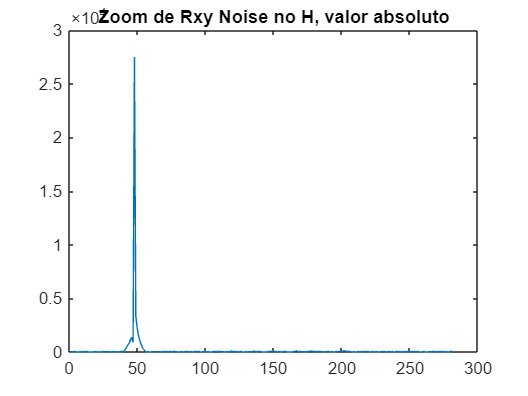


extractedCIRNorm_noise_noH = (extractedCIR_noise_noH);
figure
plot(extractedCIRNorm_noise_noH)
title("Zoom de Rxy Noise no H, valor absoluto")


Rxy = xcorr(rxDataWithH,txFiltered');
% figure
% plot(abs(Rxy))
% title("Correlación cruzada Rxy, valor absoluto")

% Suppose:
%   Rxy is your large estimated correlation data array (length M >> length(H))
%   H   is your known or ideal channel impulse response (length L)

[extractedCIR, startPos, corrVals, lagVals] = locateCIR(abs(Rxy), H);

% Print results
fprintf('The best alignment starts at index %d\n', startPos);

The best alignment starts at index 2471979


fprintf('Extracted CIR length: %d\n', length(extractedCIR));

Extracted CIR length: 281


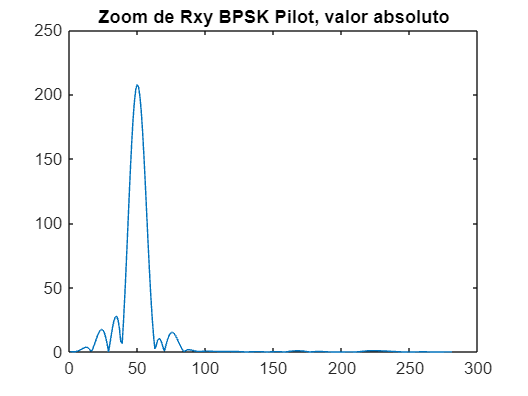


% Now "extractedCIR" should be the segment of Rxy 
% that most closely matches your original H.

extractedCIRNorm = (extractedCIR);%/max(extractedCIR))%*max(H);

figure
plot(extractedCIRNorm)
title("Zoom de Rxy BPSK Pilot, valor absoluto")



noiseH = noiseHSamps;
Rxy_noise = xcorr(noiseH,noise_gaussian);


% % Intento normalizacion
% % Calculate energy of transmitted signal (E_x)
% Ex = sum(noise_gaussian.^2);  % Or use trapz() for continuous-like signals
% 
% % Normalize to get true CIR estimate
% Rxy_noise = Rxy_noise / Ex;  % This is your estimated CIR
% %


[extractedCIR_noise, startPos, corrVals, lagVals] = locateCIR(abs(Rxy_noise), H);

% Print results
fprintf('The best alignment starts at index %d\n', startPos);

The best alignment starts at index 999859


fprintf('Extracted CIR length: %d\n', length(extractedCIR_noise));

Extracted CIR length: 281


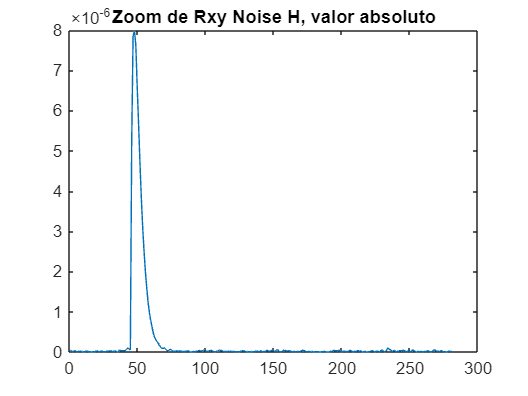



extractedCIRNorm_noise = (extractedCIR_noise)/max(extractedCIR_noise)*max(H);%extractedCIR_noise;%(extractedCIR_noise/max(extractedCIR_noise))*max(H);

figure
plot(extractedCIRNorm_noise)
title("Zoom de Rxy Noise H, valor absoluto")


% LAB CHANNEL EQ NZF

%% Parameters
numSymbols      = numSymbols;          % Number of BPSK symbols
samplesPerSym   = samplesPerSym;             % Oversampling factor (example)
rcosFilt        = rcFilter;
                  % Example sqrt raised cosine design


h_est_lab           = extractedCIRNorm;     % Example of estimated channel [adapt or replace with your own]
                                  % If you have an L-tap channel, h_est should be length L.

% rxSignal
rxChannelOut = rxDataWithH';

%% 4) Receiver: Matched Filtering
% First, refilter with rcosFilt
rxMatchedFull = filter(rcosFilt, 1, rxChannelOut);

% Compensate the filter delay
rxMatchedFull = rxMatchedFull(filtDelay+1 : end-filtDelay);

%% 5) Frequency-Domain Zero-Forcing
%
% We’ll do the FFT-based zero-forcing on rxMatchedFull.
% The length of rxMatchedFull is typically numSymbols*samplesPerSym
% minus some samples due to filter conv. Let’s call that length L.
L = length(rxMatchedFull);

% We want to avoid circular convolution issues:
Nfft = 2^nextpow2(L + length(h_est_lab) - 1);  % a safe FFT size

% Zero-pad the received signal
rxPadded = [rxMatchedFull; zeros(Nfft - L, 1)];

% Zero-pad the channel as well
hPadded  = [h_est_lab(:); zeros(Nfft - length(h_est_lab), 1)];

% Go to frequency domain
RX_F = fft(rxPadded, Nfft);
H_F  = fft(hPadded, Nfft);

% Zero-forcing in frequency domain
epsilon = 1e-10;
ZF_F = RX_F .* (1./(H_F + epsilon)); 

% IFFT to get time-domain equalized signal
zfTime = ifft(ZF_F, Nfft);

% Now, zfTime has length Nfft. We only care about the first L samples
% (which correspond to the original, non-padded region).
zfTime = zfTime(1:L);


%% 6) Downsample and Symbol Decisions
% We originally had an upsample factor of 8. Let’s downsample:
rxDownsampled = downsample(zfTime, samplesPerSym);

% BPSK detection
demodBits = real(rxDownsampled) > 0;

%% 7) Calculate BER
% We might have lost some symbols at the edges due to convolution.
% Let’s figure out how many valid symbols remain. 
% If we designed everything carefully, we should still have around `numSymbols`:
validSymCount = length(demodBits);  
minLen = min(validSymCount, length(txBits));

% Compare only the overlapping region
demodBitsTrim = demodBits(1:minLen);
txBitsTrim    = txBits(1:minLen);

numErrors = sum(demodBitsTrim ~= txBitsTrim);
BER       = numErrors / minLen;

if BER >= 0.51
    BER = 1-BER;
    numErrors = minLen - numErrors;
end

% fprintf('\nFrequency-Domain Zero-Forcing Imperfect CSI Results:\n');
% fprintf('  Number of Errors = %d (out of %d symbols)\n', numErrors, minLen);
% fprintf('  BER = %g\n', BER);



% LAB CHANNEL EQ NZF

%% Parameters
rcosFilt        = rcFilter;
                  % Example sqrt raised cosine design

h_est_lab           = extractedCIRNorm_noise;     % Example of estimated channel [adapt or replace with your own]
                                  % If you have an L-tap channel, h_est should be length L.

% We want to avoid circular convolution issues:
Nfft = 2^nextpow2(L + length(h_est_lab) - 1);  % a safe FFT size

% Zero-pad the received signal
rxPadded = [rxMatchedFull; zeros(Nfft - L, 1)];

% Zero-pad the channel as well
hPadded  = [h_est_lab(:); zeros(Nfft - length(h_est_lab), 1)];

% Go to frequency domain
RX_F = fft(rxPadded, Nfft);
H_F  = fft(hPadded, Nfft);

% Zero-forcing in frequency domain
epsilon = 1e-10;
ZF_F = RX_F .* (1./(H_F + epsilon)); 

% IFFT to get time-domain equalized signal
zfTime = ifft(ZF_F, Nfft);

% Now, zfTime has length Nfft. We only care about the first L samples
% (which correspond to the original, non-padded region).
zfTime = zfTime(1:L);


%% 6) Downsample and Symbol Decisions
% We originally had an upsample factor of 8. Let’s downsample:
rxDownsampled = downsample(zfTime, samplesPerSym);

% BPSK detection
demodBits = real(rxDownsampled) > 0;

%% 7) Calculate BER
% We might have lost some symbols at the edges due to convolution.
% Let’s figure out how many valid symbols remain. 
% If we designed everything carefully, we should still have around `numSymbols`:
validSymCount = length(demodBits);  
minLen = min(validSymCount, length(txBits));

% Compare only the overlapping region
demodBitsTrim = demodBits(1:minLen);
txBitsTrim    = txBits(1:minLen);

numErrors_noise = sum(demodBitsTrim ~= txBitsTrim);
BER_noise       = numErrors_noise / minLen;

if BER_noise >= 0.51
    BER_noise = 1-BER_noise;
    numErrors_noise = minLen - numErrors_noise;
end



% LAB CHANNEL EQ NZF

%% Parameters
rcosFilt        = rcFilter;
                  % Example sqrt raised cosine design

h_est_lab           = H;     % Example of estimated channel [adapt or replace with your own]
                                  % If you have an L-tap channel, h_est should be length L.

% We want to avoid circular convolution issues:
Nfft = 2^nextpow2(L + length(h_est_lab) - 1);  % a safe FFT size

% Zero-pad the received signal
rxPadded = [rxMatchedFull; zeros(Nfft - L, 1)];

% Zero-pad the channel as well
hPadded  = [h_est_lab(:); zeros(Nfft - length(h_est_lab), 1)];

% Go to frequency domain
RX_F = fft(rxPadded, Nfft);
H_F  = fft(hPadded, Nfft);

% Zero-forcing in frequency domain
epsilon = 1e-10;
ZF_F = RX_F .* (1./(H_F + epsilon)); 

% IFFT to get time-domain equalized signal
zfTime = ifft(ZF_F, Nfft);

% Now, zfTime has length Nfft. We only care about the first L samples
% (which correspond to the original, non-padded region).
zfTime = zfTime(1:L);


%% 6) Downsample and Symbol Decisions
% We originally had an upsample factor of 8. Let’s downsample:
rxDownsampled = downsample(zfTime, samplesPerSym);

% BPSK detection
demodBits = real(rxDownsampled) > 0;

%% 7) Calculate BER
% We might have lost some symbols at the edges due to convolution.
% Let’s figure out how many valid symbols remain. 
% If we designed everything carefully, we should still have around `numSymbols`:
validSymCount = length(demodBits);  
minLen = min(validSymCount, length(txBits));

% Compare only the overlapping region
demodBitsTrim = demodBits(1:minLen);
txBitsTrim    = txBits(1:minLen);

numErrors_PCSI = sum(demodBitsTrim ~= txBitsTrim);
BER_PCSI       = numErrors_PCSI / minLen;

if BER_PCSI >= 0.51
    BER_PCSI = 1-BER_PCSI;
    numErrors_PCSI = minLen - numErrors_PCSI;
end

fprintf('\nImperfect BPSK-pilot-CSI Results:\n');


Imperfect BPSK-pilot-CSI Results:


fprintf('  Number of Errors = %d (out of %d symbols)\n', numErrors, minLen);

  Number of Errors = 1278 (out of 247170 symbols)


fprintf('  BER = %g\n', BER);

  BER = 0.00517053



fprintf('\nImperfect noise-CSI Results:\n');


Imperfect noise-CSI Results:


fprintf('  Number of Errors = %d (out of %d symbols)\n', numErrors_noise, minLen);

  Number of Errors = 0 (out of 247170 symbols)


fprintf('  BER = %g\n', BER_noise);

  BER = 0



fprintf('\nPerfect CSI Results:\n');


Perfect CSI Results:


fprintf('  Number of Errors = %d (out of %d symbols)\n', numErrors_PCSI, minLen);

  Number of Errors = 0 (out of 247170 symbols)


fprintf('  BER = %g\n', BER_PCSI);

  BER = 0


toc

Elapsed time is 11.070479 seconds.


% =============================================
% RMS DELAY SPREAD CALCULATION FROM CIR (Real Measurements)
% =============================================

%clc; clear; close all;

%% Load CIR Data (Replace with your data)
% Format: h = [sample1; sample2; ...; sample281] (complex or real)
% Example: Synthetic CIR with 3 multipath components + noise
Nrms = 281;                    % Number of samples
dtrms = 1e-10;                  % Sampling interval 
trms = (0:Nrms-1)' * dtrms;          % Time vector

% Synthetic CIR (replace with your measured data)
% h = zeros(N,1);
% h(50) = 0.8 + 0.2j;         % First path (strongest)
% h(70) = 0.3 - 0.5j;         % Second path
% h(120) = 0.1 + 0.1j;        % Third path
% h = Final_response';%h + 0.05*(randn(N,1) + 1j*randn(N,1)); % Add noise

h_rec = extractedCIRNorm_noise;%MeanCIRog(i,:)';


%% Step 1: Compute Power Delay Profile (PDP)
Prms = abs(h_rec).^2;              % Power in linear scale

%% Step 2: Noise Thresholding
threshold_percent = 0.03;     % 10% of peak power threshold
threshold = threshold_percent * max(Prms);
valid_indices = Prms >= threshold;
P_clean = Prms(valid_indices);
tau_clean = trms(valid_indices); % Delays of valid components

%% Step 3: Calculate RMS Delay Spread
if sum(P_clean) > 0
    mean_tau = sum(P_clean .* tau_clean) / sum(P_clean);
    mean_tau_sq = sum(P_clean .* tau_clean.^2) / sum(P_clean);
    rms_delay = sqrt(mean_tau_sq - mean_tau^2);
else
    error('Threshold too high: No valid multipath components detected.');
end

%% Display Results
fprintf('===== Results =====\n');

===== Results =====


fprintf('Sampling Interval (dt): %.2f ns\n', dtrms*1e9);

Sampling Interval (dt): 0.10 ns


fprintf('Mean Excess Delay: %.2f ns\n', mean_tau*1e9);

Mean Excess Delay: 4.83 ns


fprintf('RMS Delay Spread: %.2f ns\n', rms_delay*1e9);

RMS Delay Spread: 0.24 ns


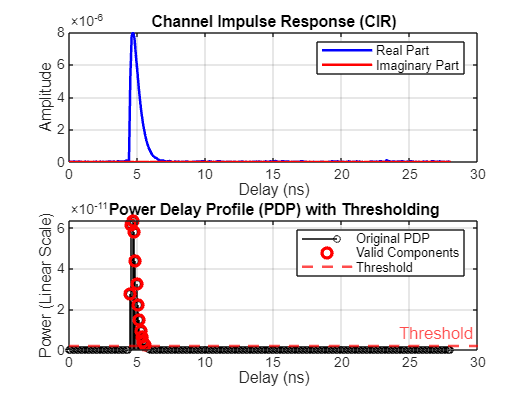


%% Visualization
figure;

% Plot CIR (Real and Imaginary Parts)
subplot(2,1,1);
plot(trms*1e9, real(h_rec), 'b', 'LineWidth', 1.5); hold on;
plot(trms*1e9, imag(h_rec), 'r', 'LineWidth', 1.5);
xlabel('Delay (ns)');
ylabel('Amplitude');
title('Channel Impulse Response (CIR)');
legend('Real Part', 'Imaginary Part');
grid on;

% Plot PDP with Threshold
subplot(2,1,2);
stem(trms*1e9, Prms, 'k', 'MarkerSize', 4, 'LineWidth', 0.5); hold on;
plot(tau_clean*1e9, P_clean, 'ro', 'MarkerSize', 6, 'LineWidth', 2);
yline(threshold, '--r', 'Threshold', 'LineWidth', 1.5);
xlabel('Delay (ns)');
ylabel('Power (Linear Scale)');
title('Power Delay Profile (PDP) with Thresholding');
legend('Original PDP', 'Valid Components', 'Threshold');
grid on;


function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end



function [startIndex, corrVec, lagVec] = findPreambleStart(rxSignal, preambleSignal)
% FINDPREAMBLESTART Finds where a known preamble begins in a received signal
%   [startIndex, corrVec, lagVec] = findPreambleStart(rxSignal, preambleSignal)
%
% INPUTS:
%   rxSignal       : The full received signal (row or column vector).
%   preambleSignal : The known preamble samples (row or column vector).
%
% OUTPUTS:
%   startIndex : The estimated index in rxSignal where the preamble starts.
%   corrVec    : The cross-correlation array (for optional debugging/plotting).
%   lagVec     : The corresponding lags vector from xcorr.

    % Ensure column vectors for consistency
    rxSignal       = rxSignal(:);
    preambleSignal = preambleSignal(:);

    % 1) Cross-correlation
    [corrVec, lagVec] = xcorr(rxSignal, preambleSignal);

    % 2) Find the lag where correlation magnitude is maximum
    [~, idxMax] = max(abs(corrVec));

    bestLag = lagVec(idxMax);

    % 3) Convert that lag to a start index in rxSignal
    %
    %   If bestLag >= 0:
    %       preamble starts at sample (bestLag + 1)
    %   If bestLag < 0, the best alignment is "before" rxSignal's first sample, 
    %   so effectively the start is near index 1. We'll clamp it to avoid negative indexing.
    %
    startIndex = bestLag + 1;  % +1 because MATLAB is 1-based indexing

    if startIndex < 1
        startIndex = 1;
    end

    % Optionally, you can check if the entire preamble fits in rxSignal:
    if startIndex + length(preambleSignal) - 1 > length(rxSignal)
        warning('Preamble extends beyond the length of rxSignal. Check capture length.');
    end
end


function [extractedCIR, startIndex, corrVals, lags] = locateCIR(Rxy, H)
% LOCATECIR finds the segment in Rxy that best matches the known channel H.
%
%   [extractedCIR, startIndex, corrVals, lags] = locateCIR(Rxy, H)
%
% INPUTS:
%   Rxy : The array containing the estimated correlation data (1D vector).
%   H   : The known (or ideal) channel impulse response (1D vector).
%
% OUTPUTS:
%   extractedCIR : The segment in Rxy that best matches H (same length as H).
%   startIndex   : The index in Rxy where the match begins (1-based).
%   corrVals     : The cross-correlation array returned by xcorr.
%   lags         : The corresponding lags array from xcorr.

    % Ensure column vectors for consistency
    Rxy = Rxy(:);
    H   = H(:);

    % 1) Cross-correlate Rxy with H
    [corrVals, lags] = xcorr(Rxy, H);

    % 2) Find the lag with maximum absolute correlation
    [~, idxMax] = max(abs(corrVals));
    bestLag     = lags(idxMax);

    % 3) Convert that lag to a start index in Rxy (MATLAB is 1-based)
    %    bestLag = 0 means the alignment starts at Rxy(1).
    startIndex = bestLag + 1;

    % 4) Extract the segment from Rxy that matches H in length
    endIndex = startIndex + length(H) - 1;

    % Boundary check to avoid indexing outside Rxy
    if startIndex < 1
        startIndex = 1;
    end
    if endIndex > length(Rxy)
        endIndex = length(Rxy);
        warning('The matching segment extends beyond the length of Rxy.');
    end

    extractedCIR = Rxy(startIndex : endIndex);
end

